clear

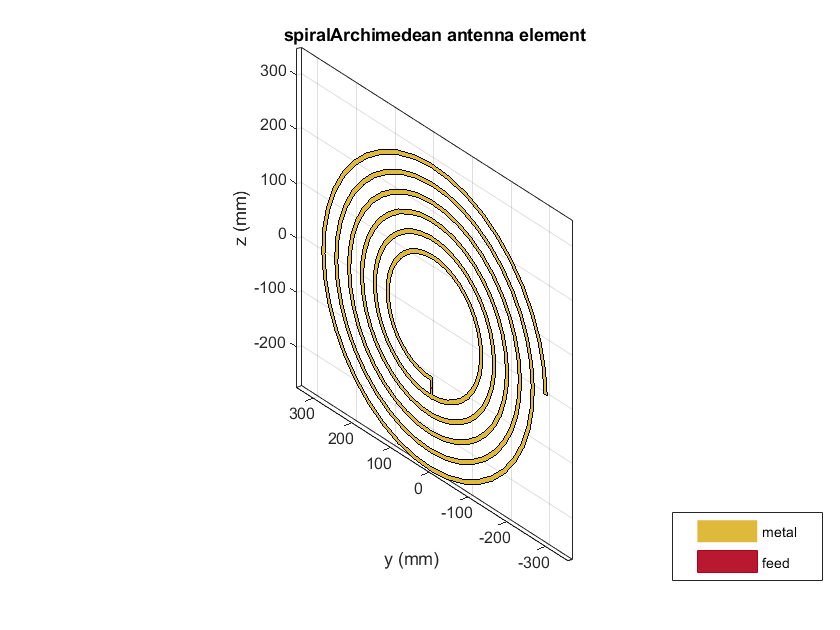

% Item 1
emi = spiralArchimedean('NumArms',1, 'Turns',6,'InnerRadius',0.1,'OuterRadius',0.3,'Tilt',90, 'TiltAxis', 'Y');
show(emi)

% Item 2
freq = linspace(10e6,20e6,50)

freq = 	1.0e+07 *

    1.0000    1.0204    1.0408    1.0612    1.0816    1.1020    1.1224    1.1429    1.1633    1.1837    1.2041    1.2245    1.2449    1.2653    1.2857    1.3061    1.3265    1.3469    1.3673    1.3878    1.4082    1.4286    1.4490    1.4694    1.4898    1.5102    1.5306    1.5510    1.5714    1.5918    1.6122    1.6327    1.6531    1.6735    1.6939    1.7143    1.7347    1.7551    1.7755    1.7959    1.8163    1.8367    1.8571    1.8776    1.8980    1.9184    1.9388    1.9592    1.9796    2.0000


imp = impedance(emi, freq)

imp = 	1.0e+02 *

   0.0000 + 0.4393i   0.0000 + 0.4506i   0.0000 + 0.4621i   0.0000 + 0.4739i   0.0000 + 0.4861i   0.0000 + 0.4986i   0.0000 + 0.5117i   0.0000 + 0.5252i   0.0000 + 0.5393i   0.0000 + 0.5541i   0.0000 + 0.5698i   0.0000 + 0.5864i   0.0000 + 0.6041i   0.0000 + 0.6233i   0.0000 + 0.6442i   0.0000 + 0.6674i   0.0000 + 0.6933i   0.0000 + 0.7229i   0.0001 + 0.7574i   0.0001 + 0.7988i   0.0001 + 0.8502i   0.0002 + 0.9168i   0.0003 + 1.0085i   0.0004 + 1.1458i   0.0009 + 1.3806i   0.0024 + 1.8905i   0.0161 + 3.9546i   0.0557 - 5.5640i   0.0040 - 1.0196i   0.0014 - 0.3272i   0.0007 - 0.0424i   0.0004 + 0.1157i   0.0003 + 0.2180i   0.0002 + 0.2910i   0.0002 + 0.3465i   0.0001 + 0.3909i   0.0001 + 0.4278i   0.0001 + 0.4593i   0.0001 + 0.4869i   0.0001 + 0.5115i   0.0001 + 0.5338i   0.0001 + 0.5544i   0.0001 + 0.5735i   0.0001 + 0.5914i   0.0000 + 0.6084i   0.0000 + 0.6246i   0.0000 + 0.6402i   0.0000 + 0.6552i   0.0000 + 0.6697i   0.0000 + 0.6839i


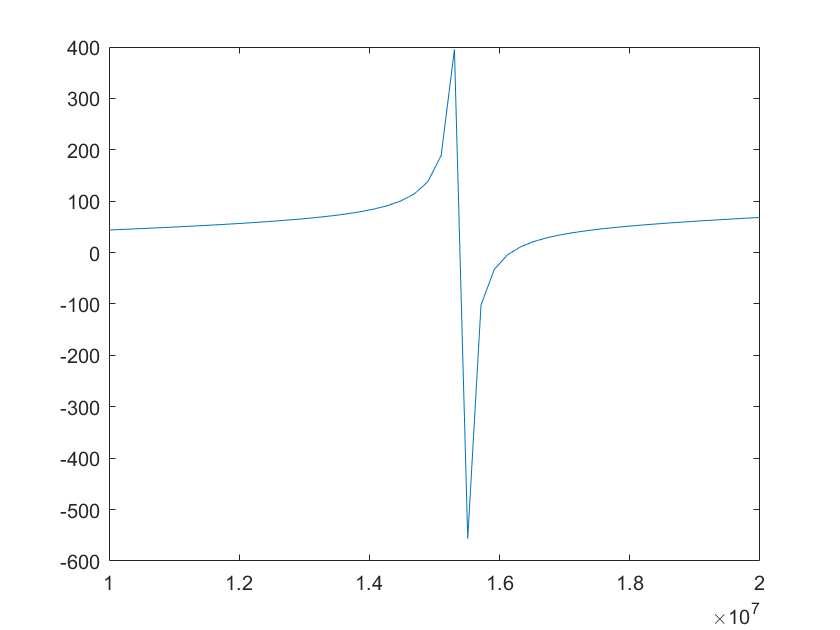

%impedance(emi, freq)
plot(freq, imag(imp))

wc = freq(imag(imp)== max(imag(imp)))

wc = 1.5306e+07

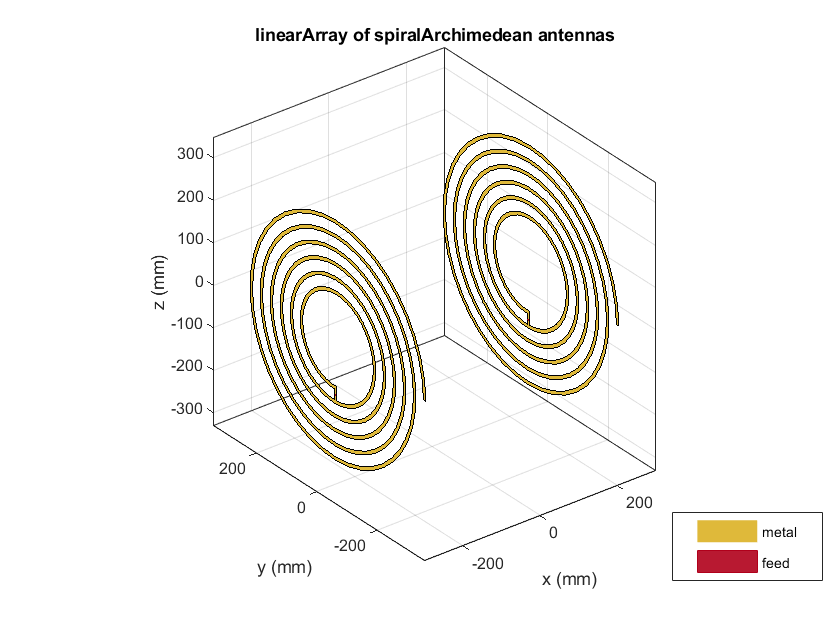

% Item 3
rec = spiralArchimedean('NumArms',1, 'Turns',6,'InnerRadius',0.1,'OuterRadius',0.3,'Tilt',90, 'TiltAxis', 'Y');
array = linearArray('Element',[emi rec],'ElementSpacing',0.5);
show(array)

% Item 4
ganhos=sparameters(array,freq);

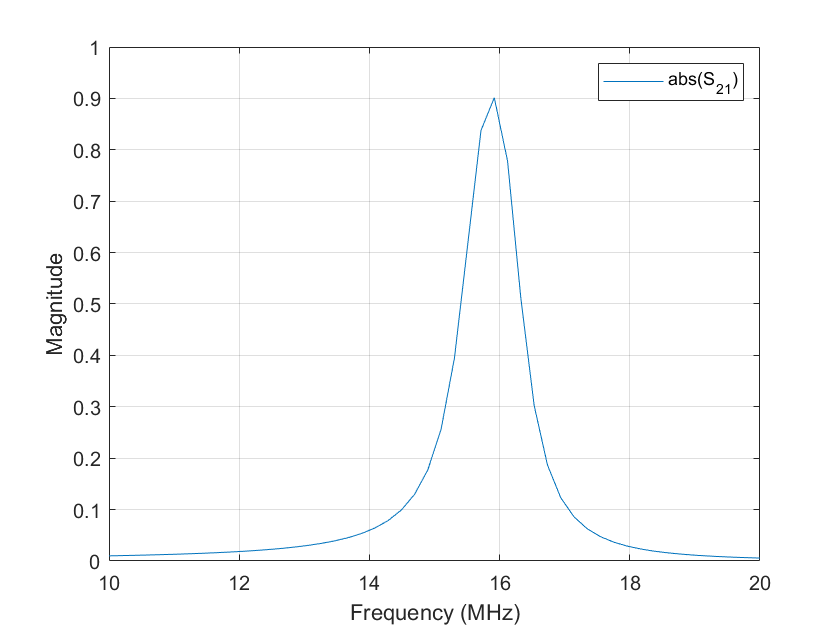

% Item 5
rfplot(ganhos,2,1,'abs')

% Item 6
x=zeros(10,50);
d=linspace(0.1,1,10);
for n=1:1:10
   array=linearArray('ElementSpacing',d(1,n));
   %array.ElementSpacing = d(1,n);
   ganhos=sparameters(array,linspace(10e6,10e7,50));
   x(n,:)=abs(rfparam(ganhos,2,1));
end

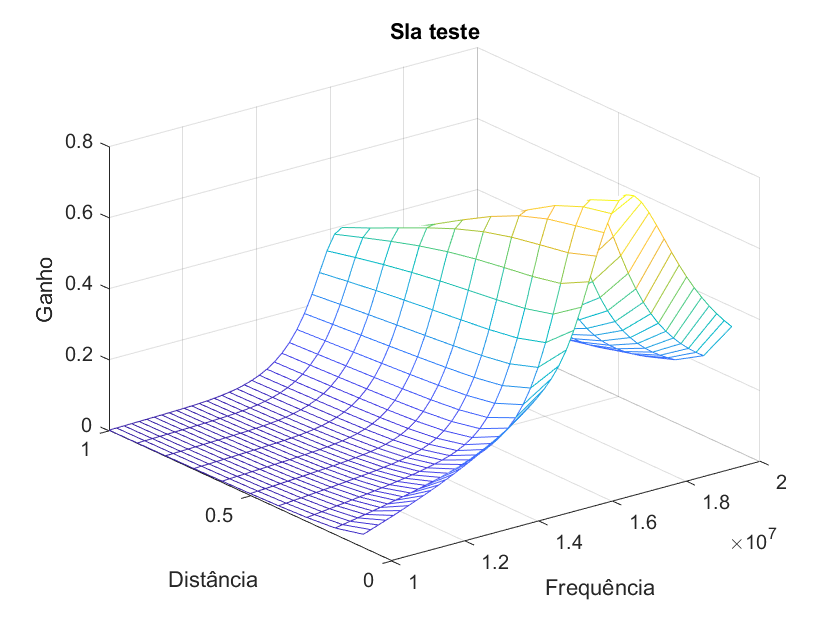

mesh(freq, d, x)
title('Sla teste')
xlabel('Frequência')
ylabel('Distância')
zlabel('Ganho')